# Práctica 4. Fórmula de Newton para interpolación polinómica.

## Implementar la interpolación polinómica mediante la fórmula de Newton de forma que permita añadir un nuevo punto de interpolación.

**a)** Para un vector $x=(x_0,\dots,x_{n+1})$ de $n+2$ componentes, y sus respectivas imágenes $y=(y_0,\dots,y_{n+1})$, queremos obtener el valor del polinomio interpolador en $N$ coordenadas $X=(X_1,\dots,X_N)$. Lo implementaremos en el **APÉNDICE A**.

La función nos debe devolver, dados $x$, $y$, $X$ y un booleano $graf$:

- El vector $Y_1$ de $N$ coordenadas, imagen en los puntos $X$ del polinomio interpolador generado con los $n+1$ primeros puntos, $(x_0,\dots,x_n)$.

- El vector $Y_2$ de $N$ coordenadas, imagen en los puntos $X$ del polinomio interpolador generado con todos los puntos, $(x_0,\dots,x_{n+1})$

- Si $graf==true$, una representación gráfica que, en la misma imagen, incluya los puntos a interpolar $(x,y)$ junto con los polinomios interpoladores, $(X,Y_1)$ y $(X,Y_2)$..

**b)** Calcula los polinomios de interpolación anteriores de la función $f(x)=\sin(x^2)$ en el intervalo $[-2,2]$ con los puntos equiespaciados dados.

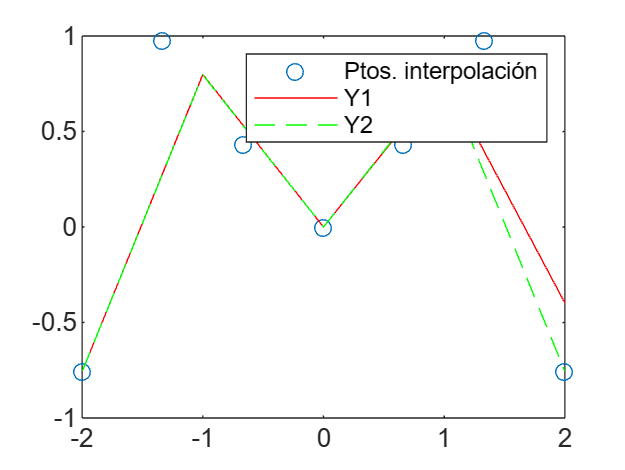

%Utiliza estos datos x, y
x=linspace(-2,2,7);
y=sin(x.^2);

%Escribe a partir de aquí tu código
[Y1,Y2] = interpNewton(x,y,linspace(-2,2,5),true);

**c)** Ahora deseamos, dado un número $n$, obtener las abscisas de Tchebychev en el intervalo $[-1,1]$. Lo implementaremos en el **APÉNDICE B**.

La función nos debe devolver, dada $n$:

- Un vector $x$ de $n+1$ componentes que sean las abscisas de Tchebychev.

**d)** Por último, calcula los polinomios de interpolación de la función $f(x)=|x|$ entre $[-1,1]$ por un lado con puntos equiespaciados y por otro con las abscisas de Thebychev. Hazlo para que en ambos casos haya $11$ puntos de interpolación. Representa ambos polinomios en una misma gráfica para comprobar cuál se adecúa mejor.

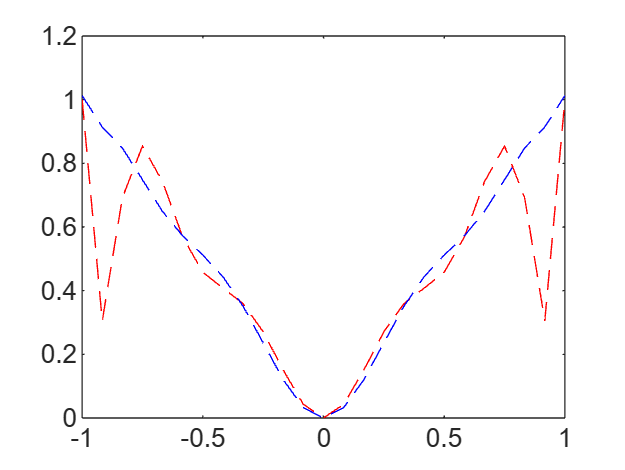

x1 = linspace(-1,1,11);
x2 = absTcheby(10);

y1 = abs(x1);
y2 = abs(x2);

X = linspace(-1,1,25);
[~,p1] = interpNewton(x1,y1,X,false);
[~,p2] = interpNewton(x2,y2,X,false);

plot(X,p1,"r--",X,p2,"b--")

% Podemos ver que usando las abcisas de Thebychev para interpolar (azul) la
% gráfica es mucho más parecida a la de la función original.

### Apéndice A. Interpolación de Newton

function [Y1,Y2]=interpNewton(x,y,X,graf)

% x = (x0,...,xn,xn+1) e y = (f(x0),...,f(xn),f(xn+1)) son los puntos por los que va a pasar el polinomio
% X = (X1,...,XN) son los valores en los que se pide evaluar el polinomio antes calculado
% (en Y1 sin usar xn+1 y en Y2 usándolo)

n = length(x) - 2;
DifDiv = zeros(n+2,n+2);


DifDiv = $\left\lbrack \begin{array}{ccccc}
f\left\lbrack x_0 \right\rbrack  & f\left\lbrack x_0 ,x_1 \right\rbrack  & \cdots \; & f\left\lbrack x_{0,} x_1 ,\ldots,x_n \right\rbrack  & f\left\lbrack x_{0,} x_1 ,\ldots,x_{n+1} \right\rbrack \\
\vdots \; & \vdots \; & \ddots \; & f\left\lbrack x_{1,} x_2 ,\ldots,x_{n+1} \right\rbrack  & \\
f\left\lbrack x_n \right\rbrack  & f\left\lbrack x_n ,x_{n+1} \right\rbrack  & \;\; &  & \\
f\left\lbrack x_{n+1} \right\rbrack  &  &  &  & 
\end{array}\right\rbrack$

% Calculamos las diferencias divididas
DifDiv(:,1) = y;
for j = 1:n+1
    for i = 0:n+1-j
        DifDiv(i+1,j+1) = (DifDiv(i+1,j) - DifDiv(i+2,j)) / (x(i+1) - x(i+1+j));
    end
end


Regla de Horner:


$$\begin{array}{l}
P_n \left(x\right)=f\left(x_o \right)+f\left\lbrack x_o ,x_1 \right\rbrack \left(x-x_0 \right)+\ldots+f\left\lbrack x_0 ,\ldots,x_n \right\rbrack \prod_{i=0}^{n-1} \left(x-x_i \right)\\
b_0 =f\left(x_0 \right)+\left(x-x_0 \right)b_1 \\
b_1 =f\left\lbrack x_0 ,x_1 \right\rbrack +\left(x-x_1 \right)b_2 \\
\vdots \;\\
b_n =f\left\lbrack x_0 ,\ldots,x_n \right\rbrack 
\end{array}$$


De esta forma, podemos evaluar el polinomio calculando regresivamente b0.

N = length(X);
Y1 = zeros(1,N) + DifDiv(1,n+1); % Y1 = (bn,...,bn)
for i = n-1:-1:0
    % (bi+1,...,bi+1) -> (f[x0,...xi]+(x-xi)bi+1,...)=(bi,...,bi)
    Y1 = DifDiv(1,i+1) + (X - x(i+1)) .* Y1;
end

% ahora utilizamos el polinomio interpolador generado con un punto más.
N = ones(1,N);
for i = 0:n
    N = N .* (X - x(i+1));
end
Y2 = Y1 + DifDiv(1,n+2) .* N;

if graf
    plot(x,y,"o",X,Y1,"-r",X,Y2,"--g")
    legend(["Ptos. interpolación","Y1","Y2"])
end

end

### Apéndice B. Abscisas de Tchebychev

function x = absTcheby(n)

x = 0:n;
x = cos((2*x+1)*pi / (2*(n+1)));

end